# Homework #2

## Build a logistic regression model to predict heart disease

#### Import data and preview 

data1 = readtable("../cleveland_data_revised.xlsx");
head(data1,5)

ans = 5×14 table
    Age    SEX    chestPain    restingBP    cholest    highBloodSugar    ECG    maxHR    angina    ECGDepression    slopeST    fluoroscopy    thalliumTest    diseaseSeverity
    ___    ___    _________    _________    _______    ______________    ___    _____    ______    _____________    _______    ___________    ____________    _______________

    63      1         1           145         233            1            2      150       0            2.3            3            0              6          

#### Build model that predicts whether individual has heart disease, and model that predicts disease severity. Evaluate using 3-fold cross validation.

X = data1{:,1:13};
Y = double(data1.diseaseSeverity > 0);   % convert logical to double

Y2 = data1.diseaseSeverity;

indices = crossvalind('kfold',size(data1,1),3);

accuracy = zeros(1,3);
precision = zeros(1,3);
recall = zeros(1,3);

rank = zeros(1,3);
avg_error = zeros(1,3);
accuracy2 = zeros(1,3);

for i = 1:3
    test = indices == i;
    train = ~test;
    
    Xtrain = X(train,:);
    Ytrain = categorical(Y(train,:));
    Ytrain2 = categorical(Y2(train,:));
    
    Xtest = X(test,:);
    Ytest = Y(test,:);
    Ytest2 = Y2(test,:);
    
    % Model 1
    [mdl1,~,stats1] = mnrfit(Xtrain,Ytrain);
    probability = mnrval(mdl1,Xtest);
    Ypred = round(probability(:,2));
    
    accuracy(i) = sum(Ypred==Ytest)/length(Ypred);
    precision(i) = sum(Ypred==1 & Ytest==1)/sum(Ypred==1);
    recall(i) = sum(Ypred==1 & Ytest==1)/sum(Ytest==1);
    
    % Model 2
    [mdl2,~,stats2] = mnrfit(Xtrain,Ytrain2);
    probability2 = mnrval(mdl2,Xtest);
    Ypred2 = round(probability2(:,2));
    
    rank(i) = corr(Ytest2,Ypred2,"type","Spearman","rows","complete");
    avg_error(i) = nanmean(abs(Ypred2-Ytest2));
    accuracy2(i) = sum(Ypred2==Ytest2)/length(Ypred2);
end


#### Model 1 Performance

mean(accuracy)

ans = 0.8086

mean(precision)

ans = 0.8165

mean(recall)

ans = 0.7844

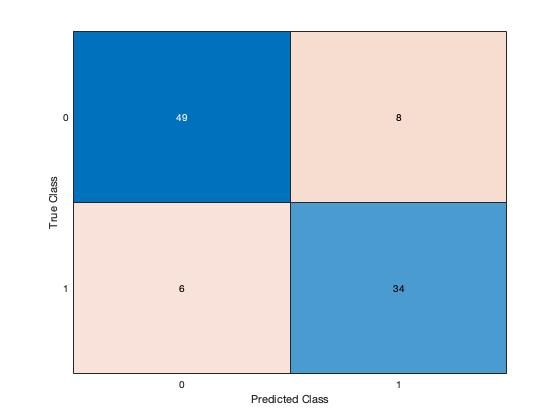

confusionchart(Ytest,Ypred);   % uses last cross-validation iteration

#### Model 2 Performance

mean(rank)

ans = 0.1006

mean(avg_error)

ans = 0.9216

mean(accuracy2)

ans = 0.5248

#### Compare models to distribution of 100 random guesses using a t-test

guess_accuracy1 = zeros(100,1);
guess_accuracy2 = zeros(100,1);
for i = 1:100
    mdl1_guess = Y(randperm(length(Ytest)));
    mdl2_guess = Y2(randperm(length(Ytest2)));
    
    guess_accuracy1(i,1) = sum(mdl1_guess == Ytest)/length(Ytest);
    guess_accuracy2(i,1) = sum(mdl2_guess == Ytest2)/length(Ytest2);
 
end
mean(guess_accuracy1)

ans = 0.5190

mean(guess_accuracy2)

ans = 0.3900

[h_mdl1, p_mdl1] = ttest2(accuracy,guess_accuracy1)

h_mdl1 = 1

p_mdl1 = 6.0614e-16

[h_mdl2, p_mdl2] = ttest2(accuracy2,guess_accuracy2)

h_mdl2 = 1

p_mdl2 = 9.7590e-09

#### Most important features from each model, based on p-value

Model 1

[p1,m1] = mink(stats1.p,5)

p1 =     0.0001
    0.0027
    0.0116
    0.0155
    0.0561


m1 =     13
    14
     5
    10
     9


% Must subtract 1 from index to account for intercept term
data1.Properties.VariableNames([12,13,4,9,8])

ans = 1×5 cell array
    {'fluoroscopy'}    {'thalliumTest'}    {'restingBP'}    {'angina'}    {'maxHR'}


Model 2

mdl2_pvalues = mean(stats2.p,2);   % take mean p-value for each features
[p2,m2] = mink(mdl2_pvalues,5)

p2 =     0.0756
    0.1073
    0.1232
    0.1717
    0.1926


m2 =      1
    13
    10
    12
    14


data1.Properties.VariableNames([12,9,11,13])

ans = 1×4 cell array
    {'fluoroscopy'}    {'angina'}    {'slopeST'}    {'thalliumTest'}


## Brain cancer survival data set

#### Import and inspect data 

data2 = readtable("Top 100 Genes.xlsx");
tail(data2,5)

ans = 5×104 table
     PATIENT_ID     SurvivalDaysOS    SurvivalDaysPF    Test     LIX1L       NEU4       TTC12       IFITM10      EIF3L       DGCR14      MRPS27     KHDRBS3      CCDC89       PHB2        TTLL1      PPAPDC1A     TNNC2        WWP2      C2orf27A       USE1        FCHSD2      EEF1G      C20orf196    RPL19P12     LYSMD1      OLIG1      ZNF780A      LUZP2       MYO15A       RPL3       PCBP3      C7orf53       TSSC1       

#### Create train and tests sets X and Y 

Xtrain = data2{data2.Test==0,5:end};
Xtest = data2{data2.Test==1,5:end};

Ytrain = data2{data2.Test==0,3};
Ytest = data2{data2.Test==1,3};

#### Build lasso model

[B1, Fit] = lasso(Xtrain,Ytrain,'CV',10); 
B1_coeff = B1(:,Fit.IndexMinMSE);
B1_intercept = Fit.Intercept(Fit.IndexMinMSE) 

B1_intercept = 458.9062

#### Build stepwise model

[B2,~,~,inmodel,stats] = stepwisefit(Xtrain,Ytrain,"display","off" );

#### Use models to predict survival (PFS). Calculate correlation and mean absolute error

Lasso

Ypred_lasso = Xtest * B1_coeff + B1_intercept;
r_lasso = corr(Ypred_lasso,Ytest)

r_lasso = 0.2258

avg_error_lasso = mean(abs(Ypred_lasso-Ytest))

avg_error_lasso = 284.4510

Stepwise

Ypred_step = Xtest(:,find(stats.PVAL < 0.05))*B2(find(stats.PVAL < 0.05)) + stats.intercept;
r_stepwise = corr(Ypred_step,Ytest)

r_stepwise = 0.4530

avg_error_stepwise = mean(abs(Ypred_step-Ytest))

avg_error_stepwise = 275.6031

## Compare regression methods with linear regession

#### Build linear regression model with top 15 correlated genes

% Find correlation of all 100 genes and then extract data for top 15 genes
r_100 = corr(Xtrain,Ytrain);
[r_15,index_15] = maxk(abs(r_100),15);

% Create new training and test sets with top 15 genes 
Xtrain_15 = Xtrain(:,index_15);
Xtest_15 = Xtest(:,index_15);

mdl = fitlm(Xtrain_15,Ytrain)

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15

Estimated Coefficients:
                   Estimate      SE       tStat        pValue  
                   ________    ______    ________    __________

    (Intercept)     457.33     56.354      8.1153    5.9897e-09
    x1              213.75     120.73      1.7704      0.087166
    x2             -160.74     114.06     -1.4093       0.16939
    x3             -33.507     159.69    -0.20982       0.83527
    x4               174.4      195.9     0.89022       0.38068
    x5              31.944     170.59     0.18725       0.85277
    x6              180.64     128.12      1.4099        0.1692
    x7       

#### Predict survival (PFS) in test set and measure model accuracy 

Ypred_norm = predict(mdl,Xtest_15);

r_norm = corr(Ytest,Ypred_norm)

r_norm = 0.0677

avg_error = mean(abs(Ypred_norm-Ytest))

avg_error = 279.0284

#### Compare correlation and number of features of 3 methods 

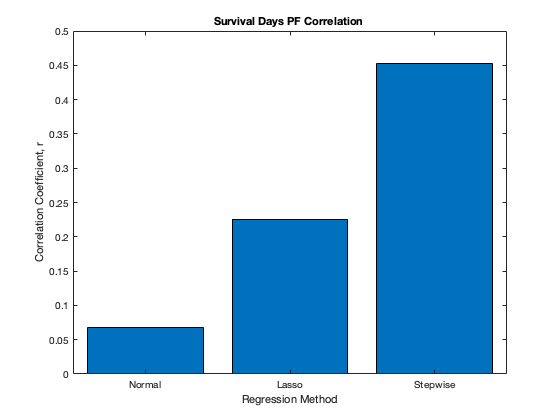

% Create labels for bar graphs
x = categorical({'Normal','Lasso','Stepwise'});
x = reordercats(x,{'Normal','Lasso','Stepwise'});

% Correlation bar graph. 
bar(x,[r_norm,r_lasso,r_stepwise])
xlabel("Regression Method")
ylabel("Correlation Coefficient, r")
title("Survival Days PF Correlation ")

% Find number of features in each model
size_lin_reg = size(mdl.Coefficients,1)-1   % subtract 1 for intercept term

size_lin_reg = 15

size_lasso = sum(B1_coeff ~= 0)

size_lasso = 31

size_stepwise = length(find(stats.PVAL < 0.05))

size_stepwise = 5

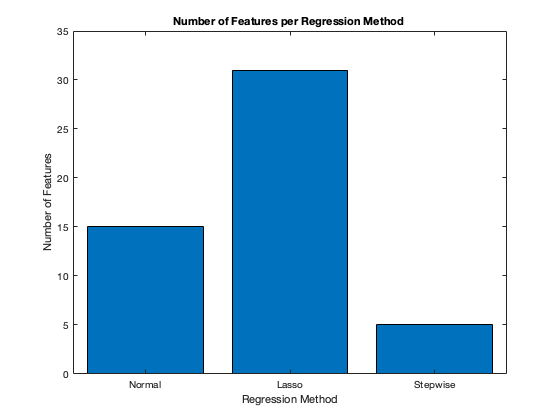

% Number of features bar graph
bar(x,[size_lin_reg,size_lasso,size_stepwise])
xlabel("Regression Method")
ylabel("Number of Features")
title("Number of Features per Regression Method ")